# Plate Reader 1

## Step 1: data loading and preparation

Add PLATERO set of functions to your working directory:

my = version('-release');
if str2double(my(1:4))<2020
addpath(genpath('rprev2020'))
else
addpath(genpath('r2020'))
end

Now, load the data resulting from the calibration experiment, written in "`filename`". This data is organized by sheets, where each sheet has one repetition of the measurements.

filename = "PlateReader1.xlsx";
colnames = {'WellID','Well','Concentration','G50','G60','G70','G80','OD'};
[dataPR, indgfp] = readexperiment(filename,"B102:I197",50:10:80,false,colnames);
size(dataPR)

ans =         3072           6


Divide the dataset into the subset with medium values (`dataPRblk`) and the set with fluorescein values (`dataPRgfp`).

datPRblk = dataPR(~indgfp,:);
datPRgfp = dataPR(indgfp,:);
disp(strcat("This data set has ", string(size(datPRblk,1)),...
" BLK observations and ", string(size(datPRgfp,1)), ...
" GFP observations."))

This data set has 512 BLK observations and 2560 GFP observations.


Obtain the partition of the fluorescein dataset into the model building set  (70%) and the model validation set (30%). A seed is set to ensure reproducibility of the results. The resulting subsets are stored as the `calibration_PR1.mat `and the `validation_PR1.mat `files.

rng(0207)
[datagfp_cal, datagfp_val] = cvsplit(datPRgfp, 0.7);
disp(strcat("The calibration data set has ", string(size(datagfp_cal,1)),...
" observations and the validation data set has ", ...
string(size(datagfp_val,1)), " observations."))

The calibration data set has 1760 observations and the validation data set has 800 observations.


data_cal_pr1 = [datPRblk; datagfp_cal];
save('calibration_PR1.mat',"data_cal_pr1")
save('validation_PR1.mat',"datagfp_val")

## Step 2: Model Building step

Load the calibration subset, fit the model and store the coefficients.

Explorative plot of missing data for each concentration level: 


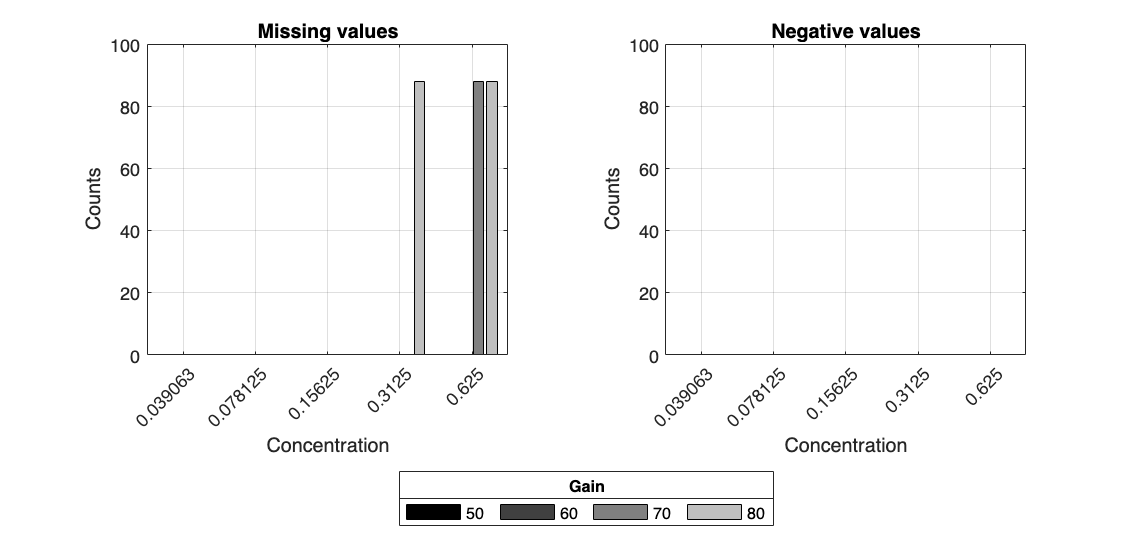

Concentration(s)0.3125, 0.625 had missing values
Concentration(s) had negative values
Gain(s)70, 80 had missing values
Gain(s) had negative values
Explorative plot of the raw F_observed Fluorescein data: 


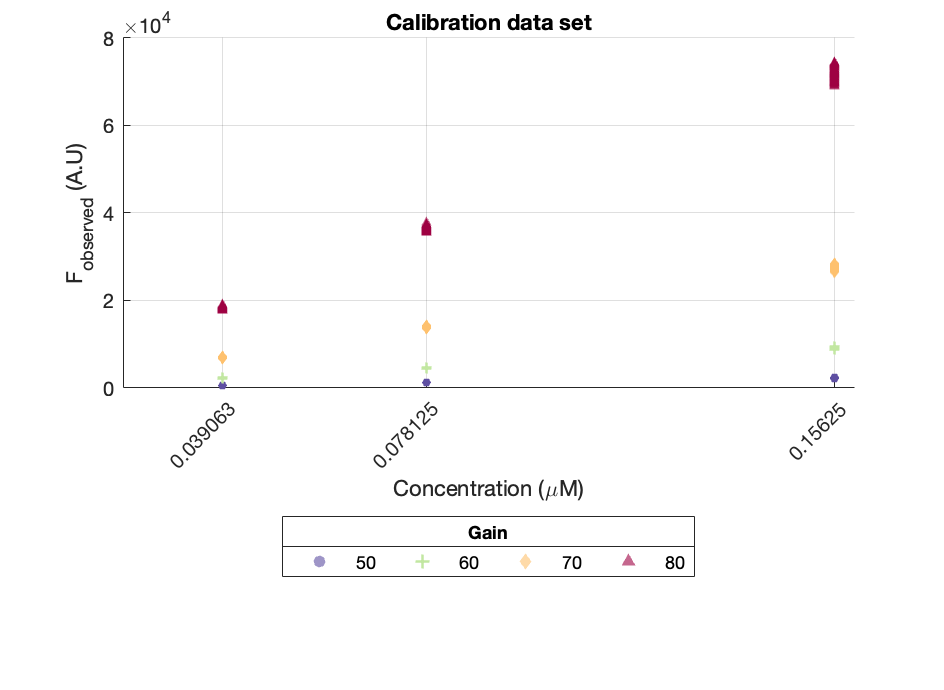

Explorative plot of the raw F_BLK data: 


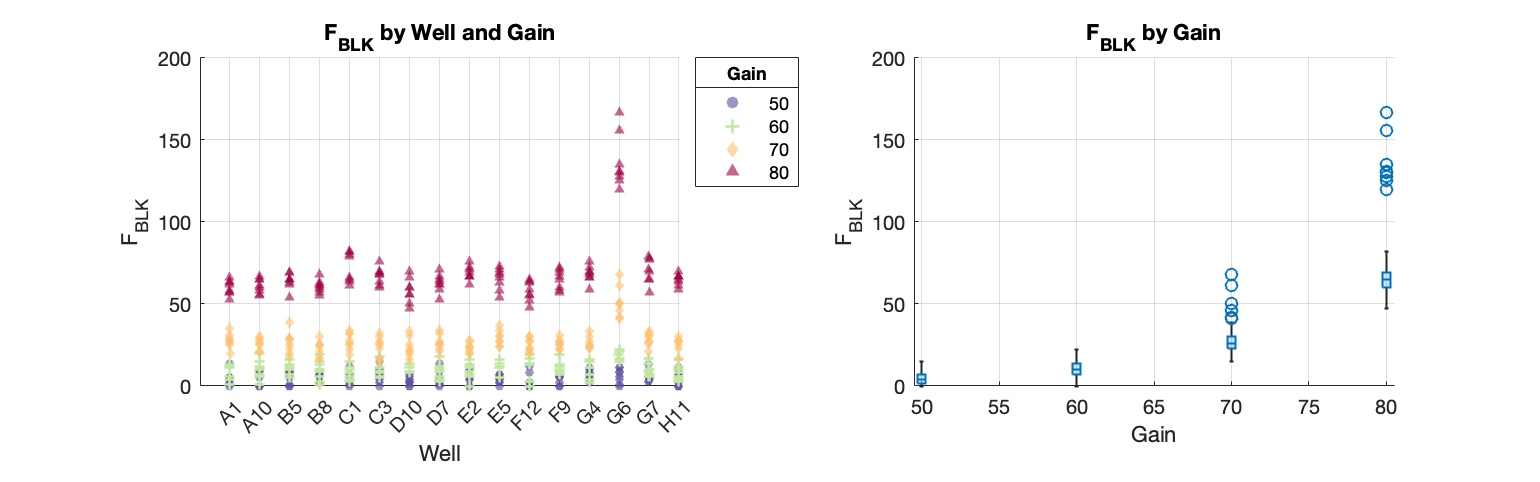

data_cal_pr1 = load("calibration_PR1.mat").data_cal_pr1;
[blk_data, flu_data_PR1] = explore_data(data_cal_pr1, nan);

Fit f_G and plot corrected data (F_reporter): 
ANOVA on coefficient b_1 for all levels of concentration


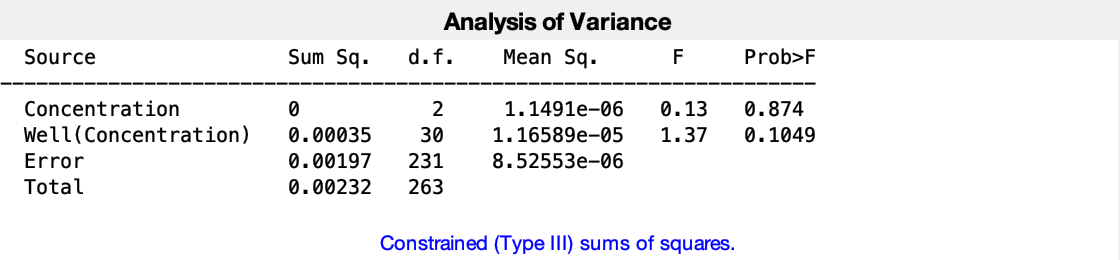

ANOVA on coefficient b_2 for all levels of concentration


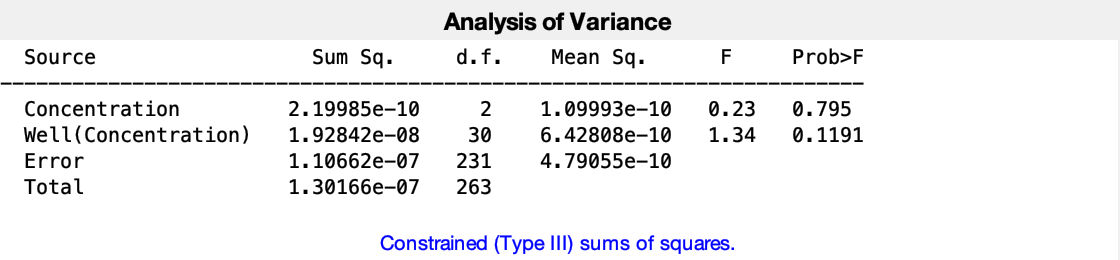

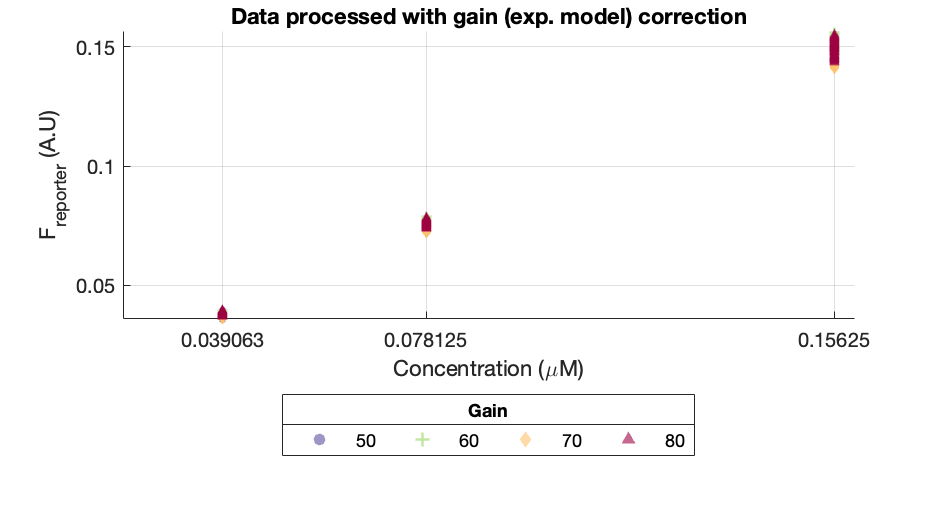

Fit f_UC and plot estimated concentration data (C): 


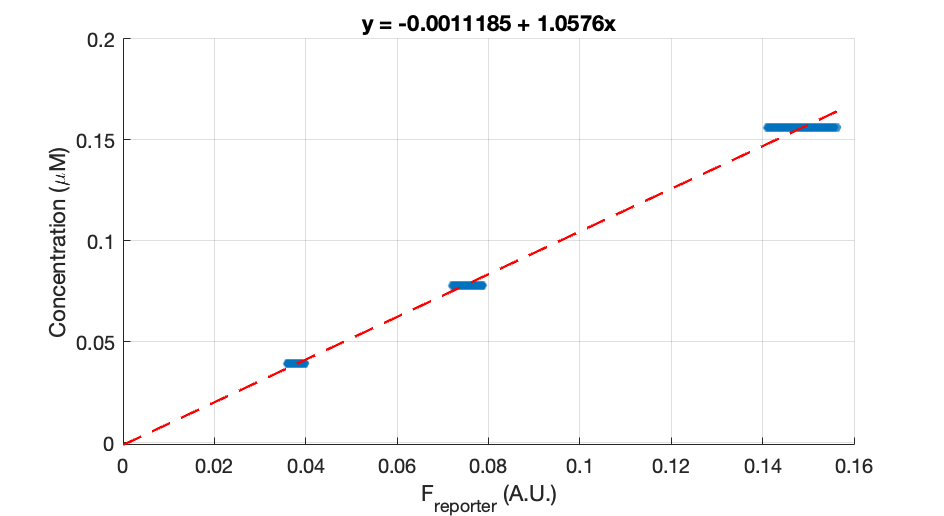

Analize the bias in the predictions and estimate the uncertainty in the predictions (s_Bias): 


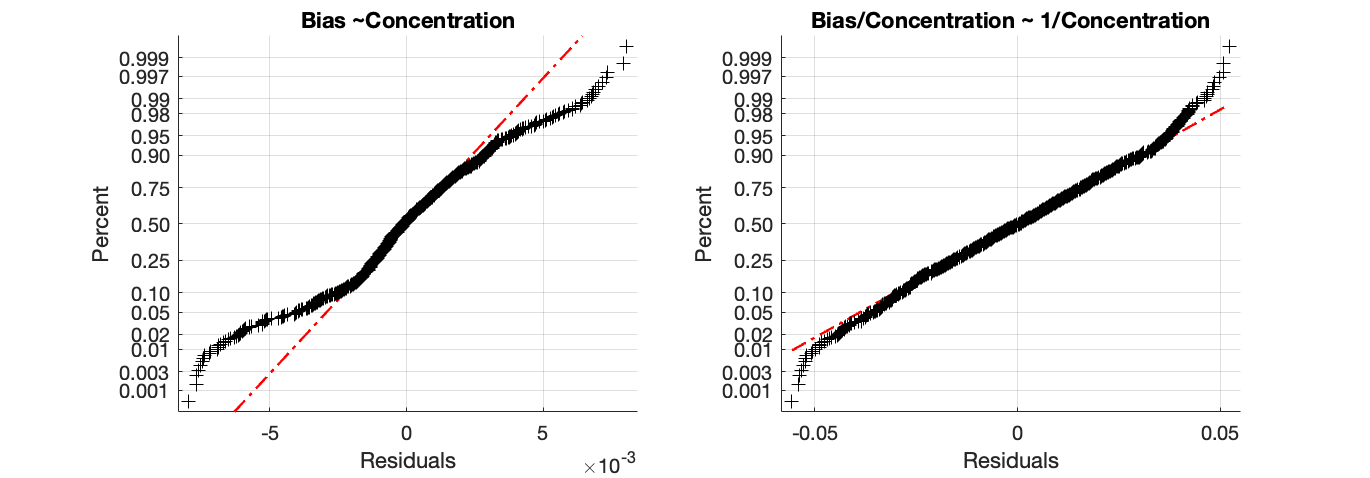

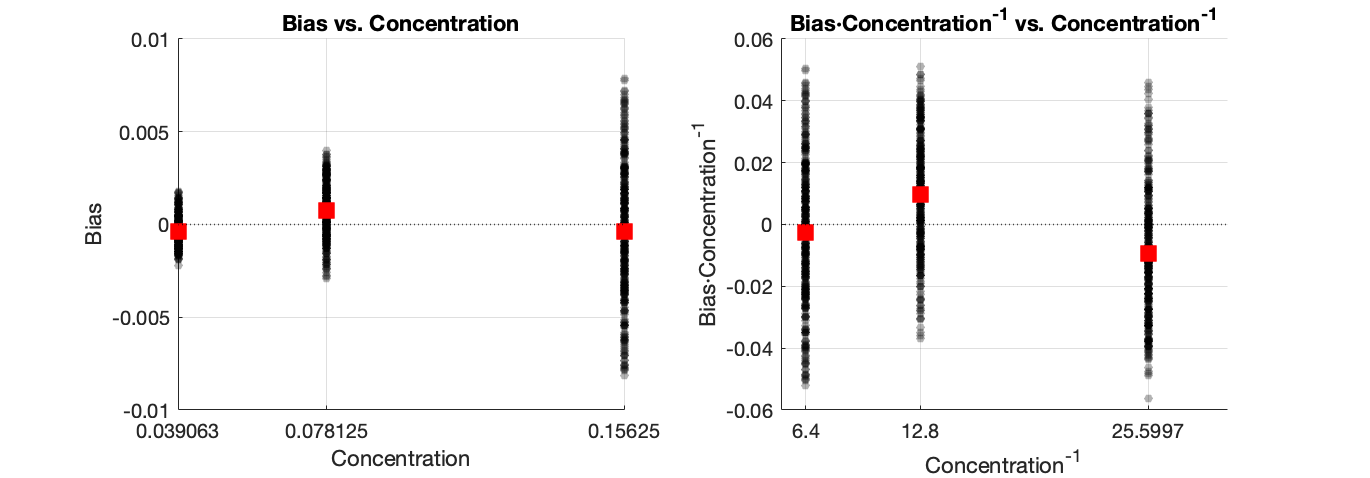

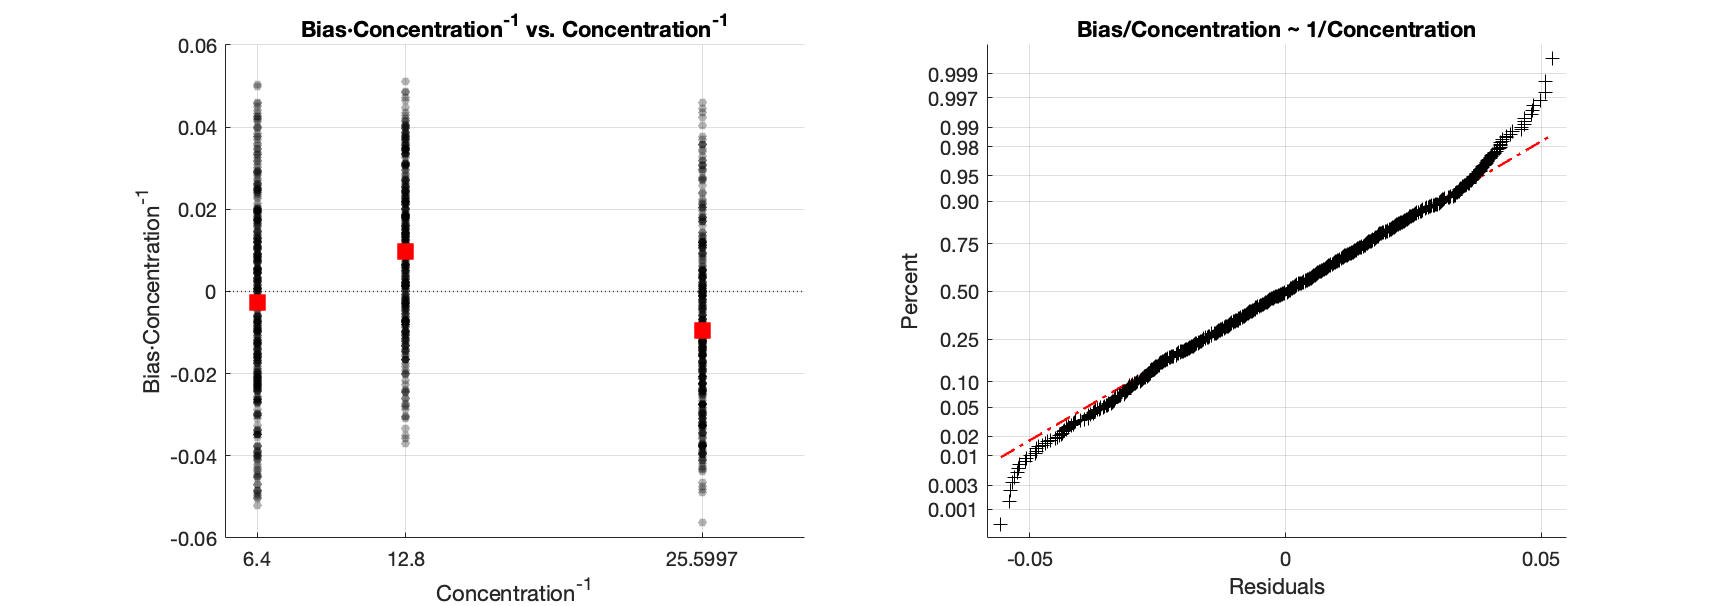

Compute error metrics for the Model Building step: 
    F_BLK (G = 50)    F_BLK (G = 60)    F_BLK (G = 70)    F_BLK (G = 80)      b1           b2            c0          c1       sBias      EDF 
    ______________    ______________    ______________    ______________    _______    __________    __________    ______    ________    ____

          4                 10                26                65          0.24298    -0.0009933    -0.0011185    1.0576    0.022472    1054



[flu_data_PR1, modelPR1, calmetrics_PR1] = fit_platero_model(blk_data, flu_data_PR1, "PR_1");

## Step 3: Model Validation step

A 15 % of the observations was missing.
Plot the Validation dataset transformed to concentration units: 


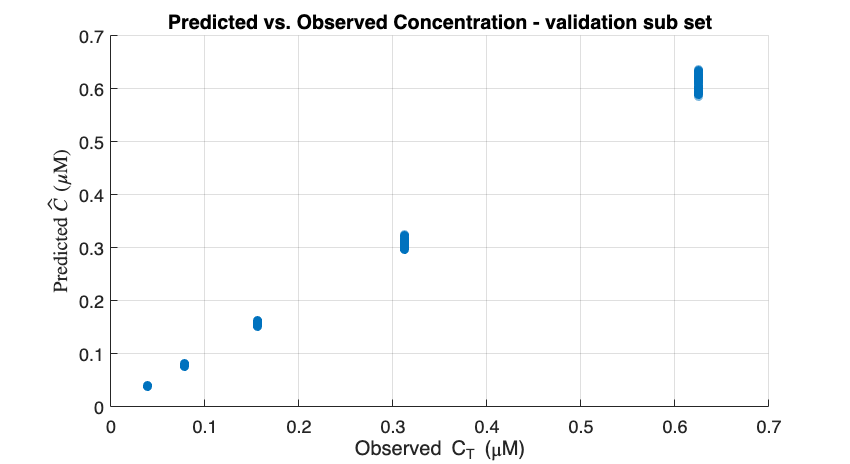

R&R Analysis: 
R & R Analysis on measurements for C = 0.039063


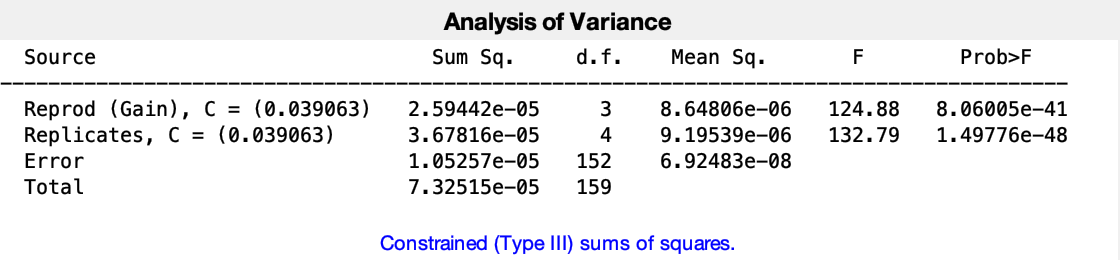

R & R Analysis on measurements for C = 0.078125


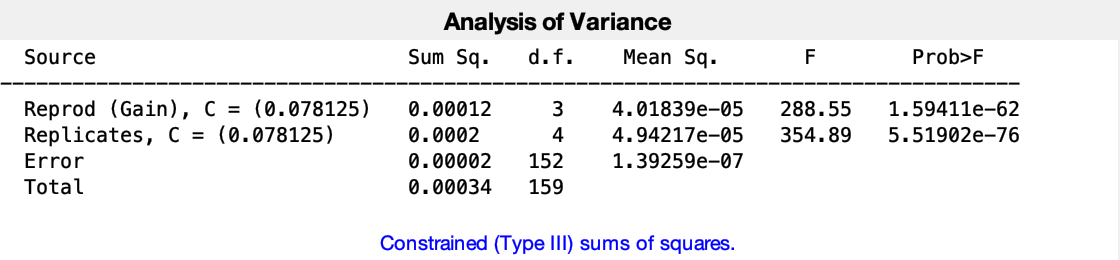

R & R Analysis on measurements for C = 0.15625


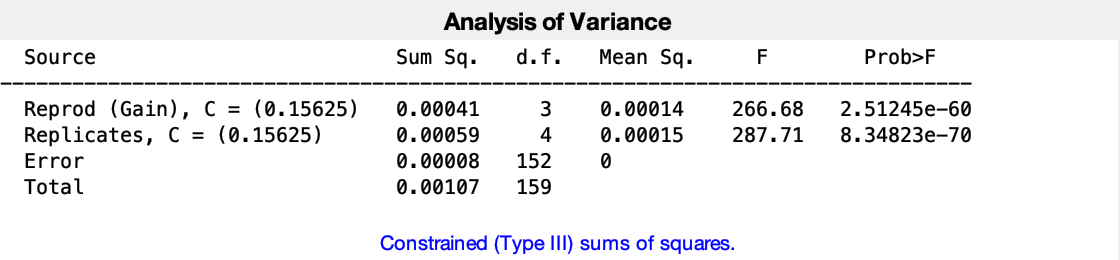

R & R Analysis on measurements for C = 0.3125


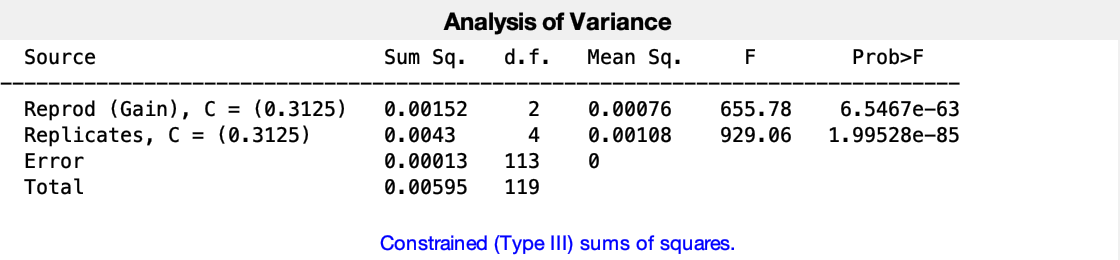

R & R Analysis on measurements for C = 0.625


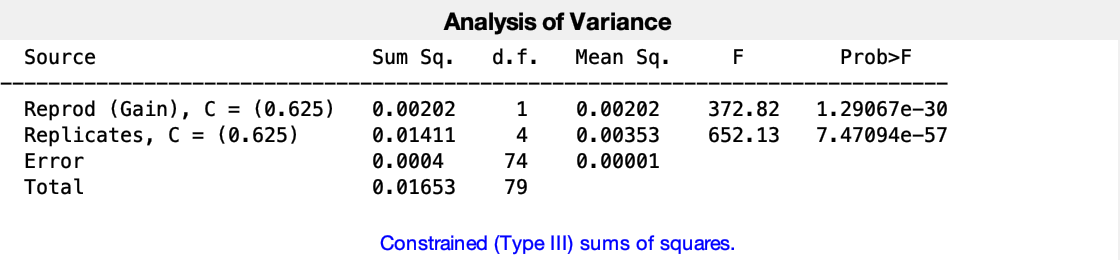

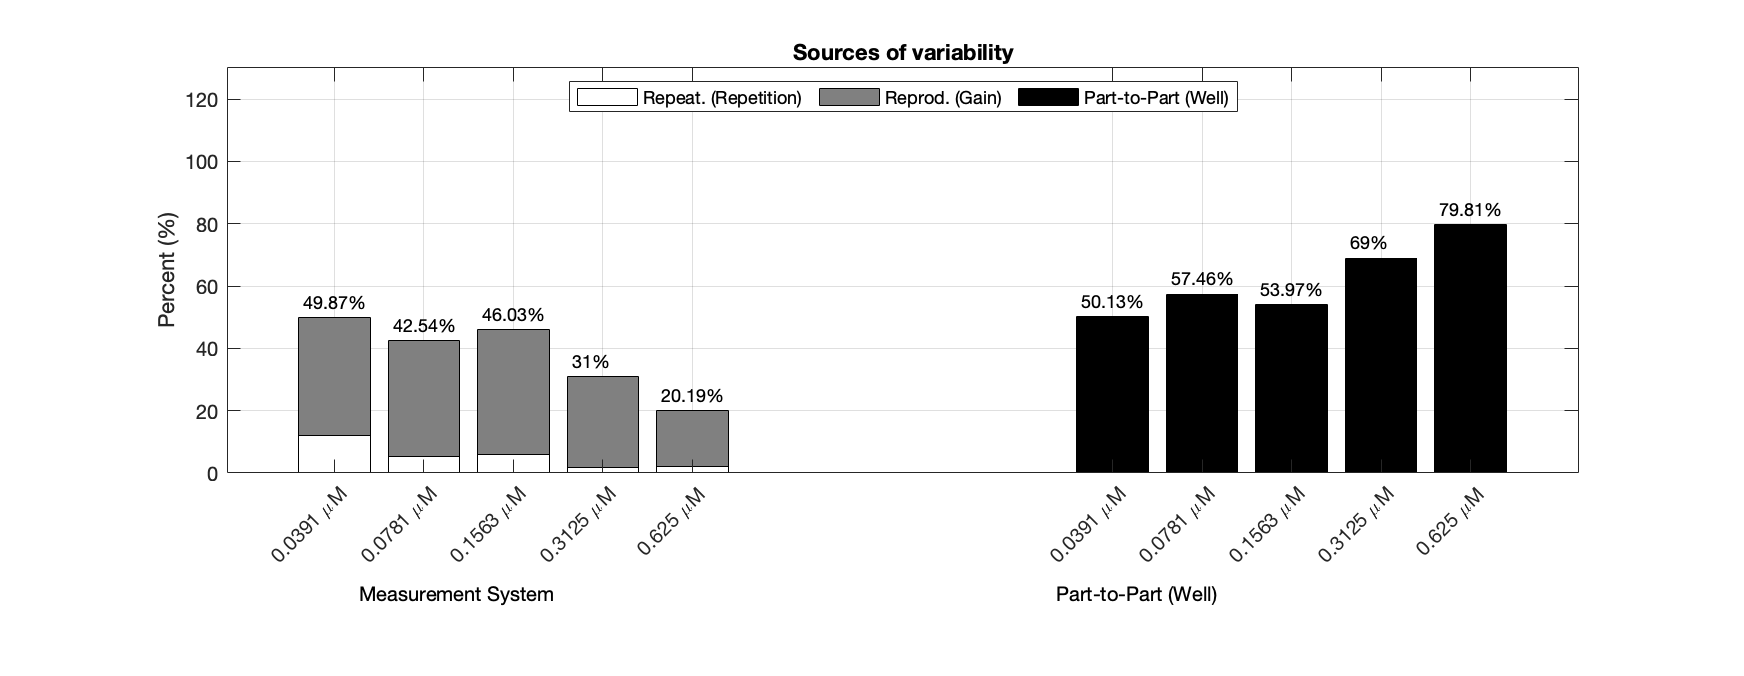

 
B&L Analysis: 


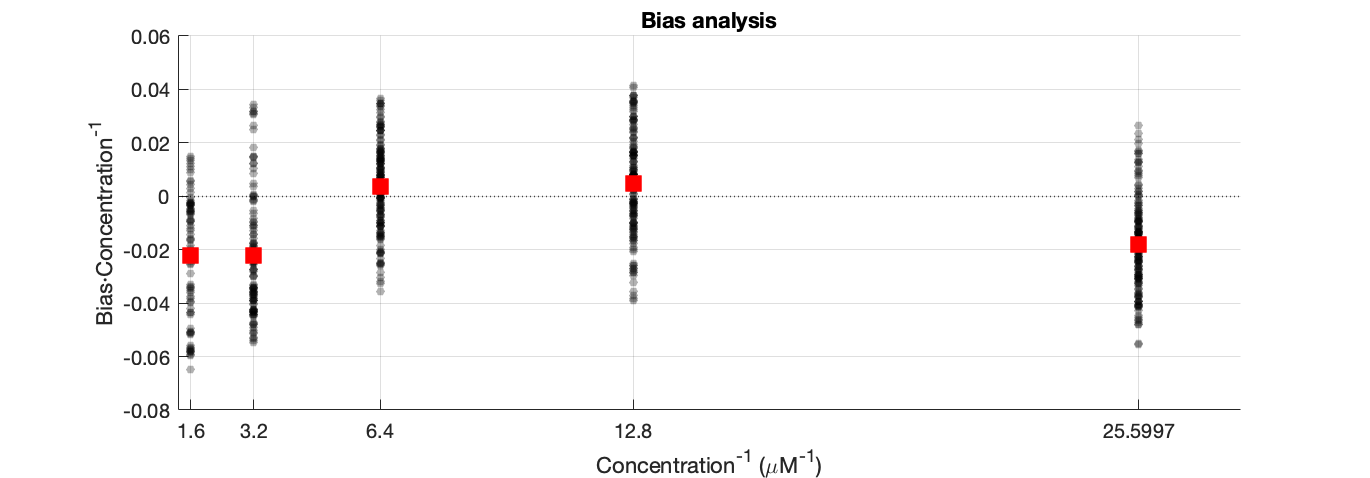

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)     -0.0078207     0.0014307     -5.4665    6.4573e-08
    x1             -7.6231e-05    0.00010005    -0.76196       0.44635


Number of observations: 680, Error degrees of freedom: 678
Root Mean Squared Error: 0.0229
R-squared: 0.000856,  Adjusted R-Squared: -0.000618
F-statistic vs. constant model: 0.581, p-value = 0.446
-------------------------------------------------------------------
Contribution of model terms to the total bias variability:
Bias Model - linear term (%): 0.7821 %
Bias Model - bias term (%): 10.1993 %
 
Confidence Intervals and Error metrics: 
        pctgeci: 91.6176
        

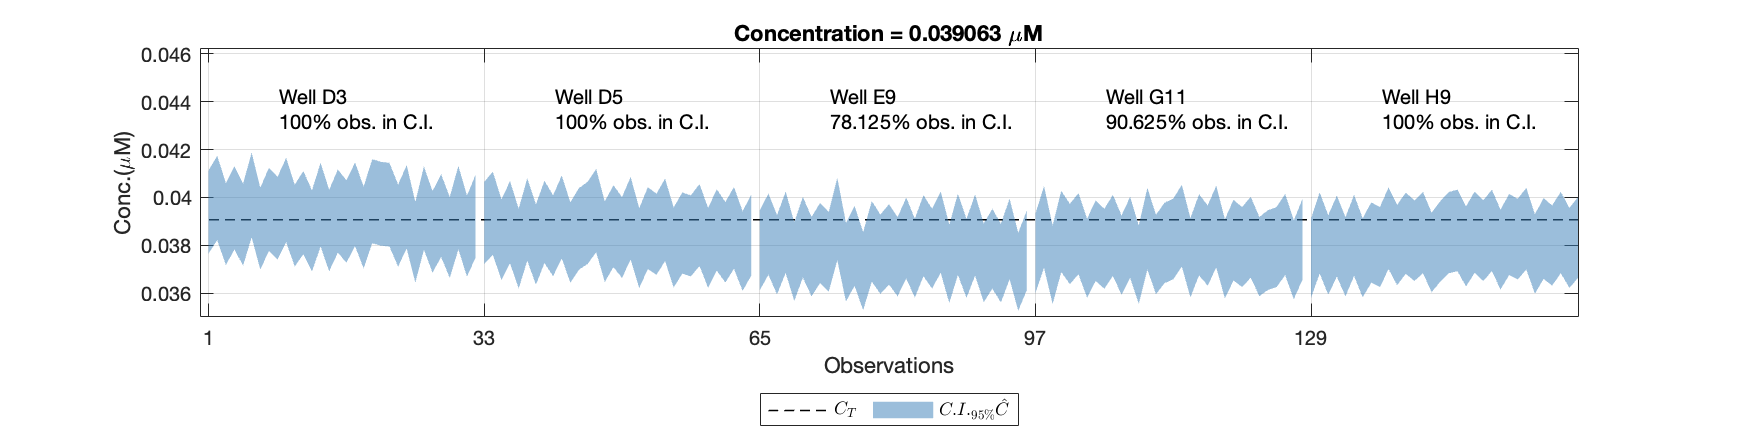

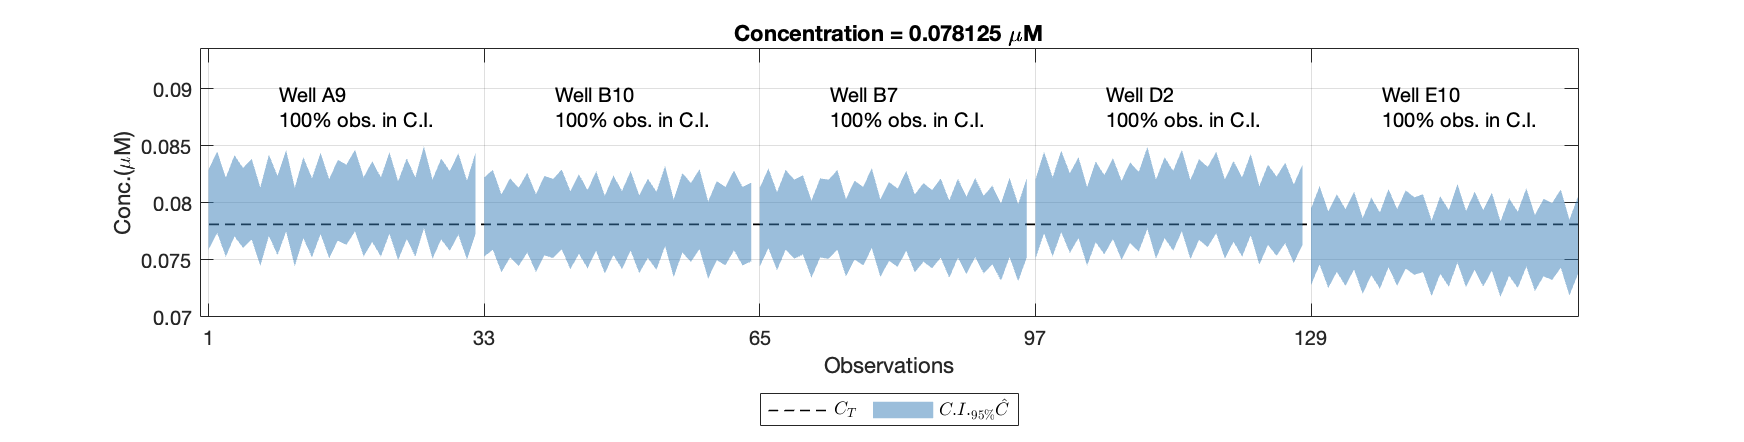

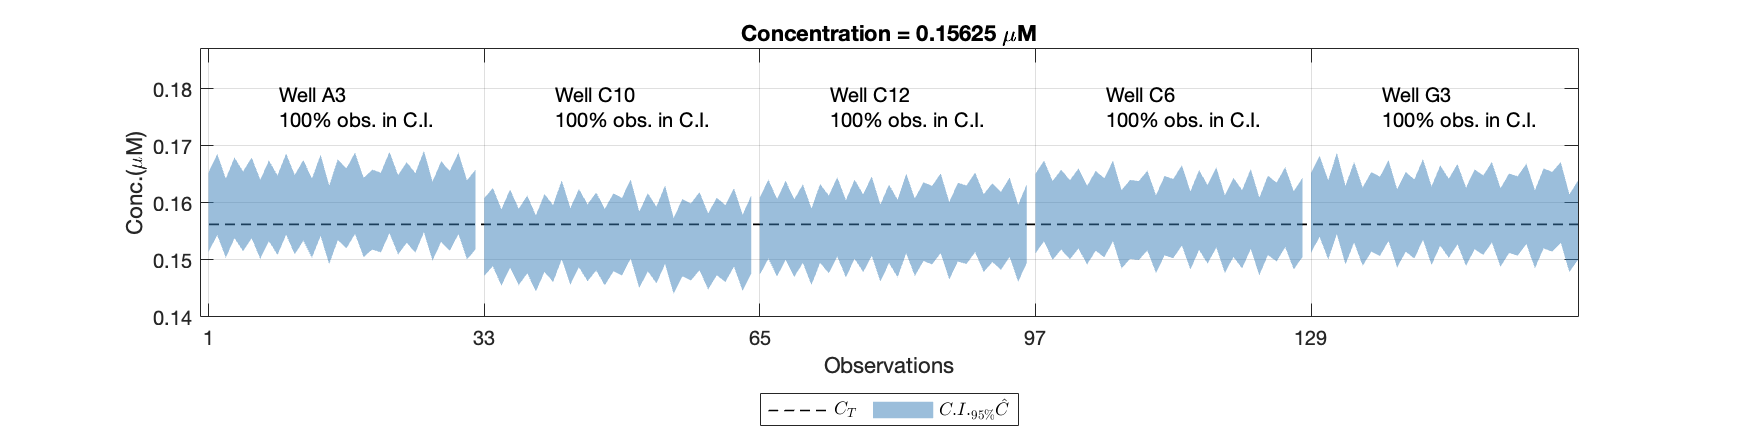

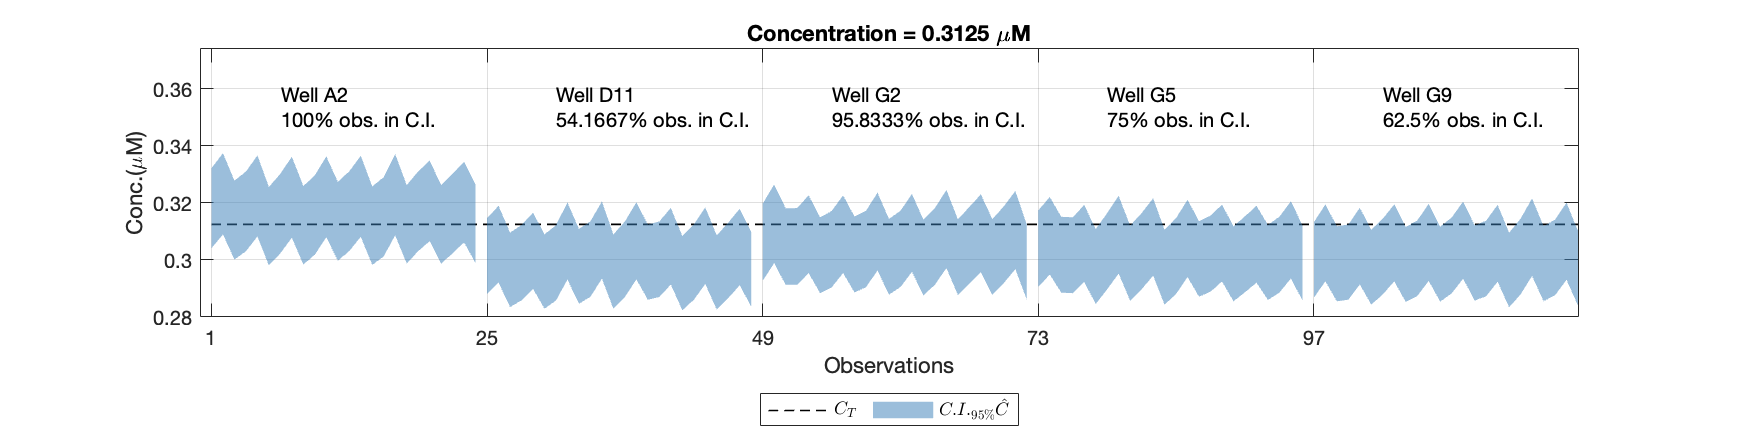

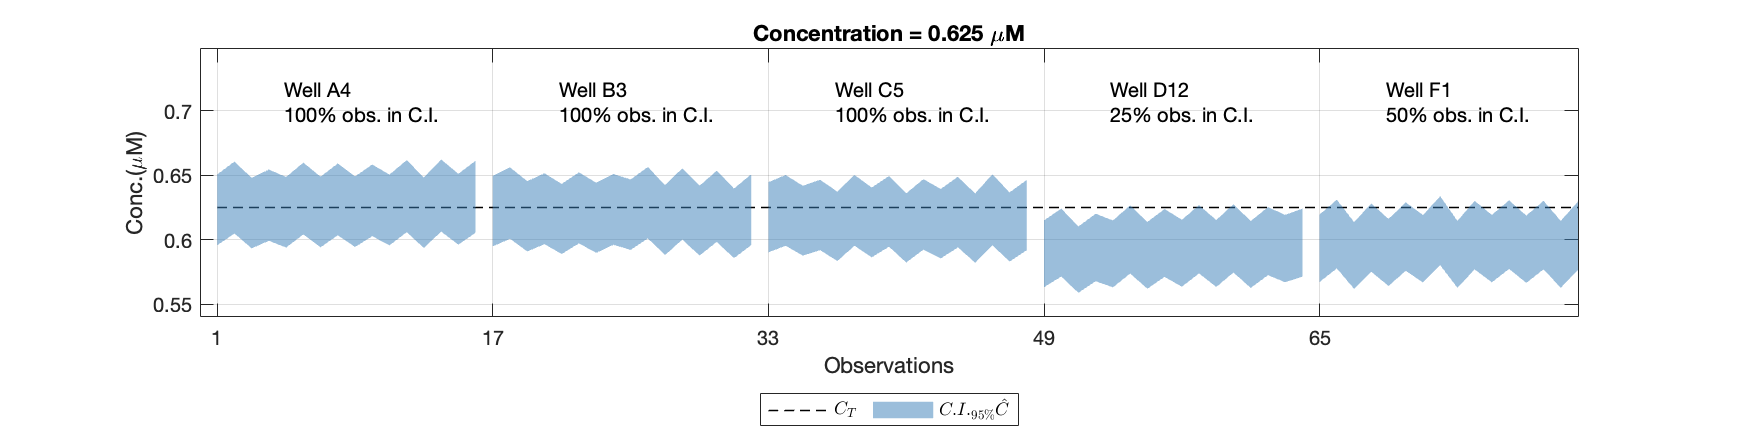

datagfp_val = load("validation_PR1.mat").datagfp_val;
uG = unique(flu_data_PR1.Gain);
uC = unique(flu_data_PR1.Concentration);
data_val_pr1 = datagfp_val(ismember(datagfp_val.Gain, uG),:);
G = unique(data_val_pr1.Gain);

% Assign the correspoding F_BLK values to each observation F_obs
data_val_pr1.Fblk = repmat(modelPR1{:,1:4}', size(data_val_pr1,1)/length(G),1);

% Run the model on the validation set
[data_val_pr1, valmetrics_inrange, vprocv] = use_platero_model(data_val_pr1, ...
    modelPR1,"PR_1");


% Comparison between calibration-set and validation-set metrics
% load(strcat(dirdatasave,'cal_results.mat'))
perftable = table([calmetrics_PR1.mse;valmetrics_inrange.mse],...
[calmetrics_PR1.minrelerror;valmetrics_inrange.minrelerror]*100,...
[calmetrics_PR1.maxrelerror;valmetrics_inrange.maxrelerror]*100,...
'RowNames',{'Calibration', 'Validation (within range)'},...
'VariableNames',{'MSE','Min.Rel.Error (%)','Max.Rel.Error (%)'});
display(perftable)

perftable = 2×3 table
                                    MSE        Min.Rel.Error (%)    Max.Rel.Error (%)
                                 __________    _________________    _________________

    Calibration                  5.6728e-06        0.0040339             5.6197      
    Validation (within range)    6.6503e-05        0.0017022             6.4732      
